% MidTreadQuantization
clc;
clear;

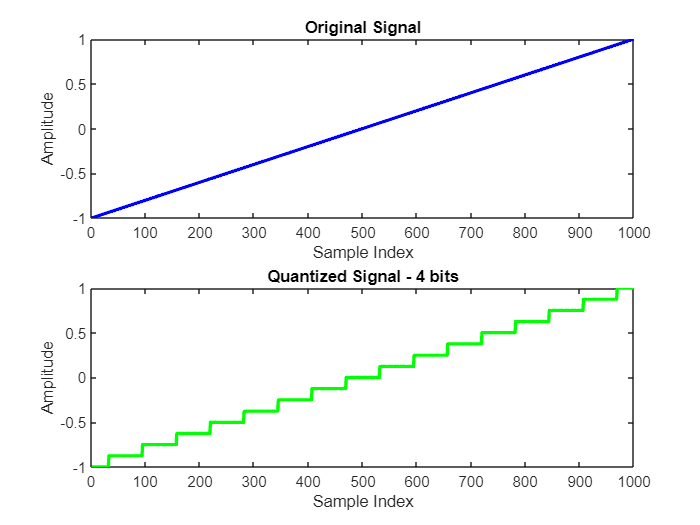

ip_sig=linspace(-1, 1, 1000);
num_bits = 4;
treadQuantizedOutput=midTreadQuantization(ip_sig,num_bits);

figure;
subplot(2,1,1);
plot(ip_sig,'b','LineWidth',2);
title('Original Signal');
xlabel('Sample Index');
ylabel('Amplitude');
hold on
subplot(2,1,2);
plot(treadQuantizedOutput,'g','LineWidth',2);
title(['Quantized Signal - ',num2str(num_bits),' bits']);
xlabel('Sample Index');
ylabel('Amplitude');

function QuantizedOutput=midTreadQuantization(ip_sig,num_bits)
    
    % Input signal should be in the range [-1,1]
    % numb_bits is the number of bits for quantization

    % Calculate the step size
    step_size=2/(2^(num_bits));

    % Quantize the input signal
    QuantizedOutput=round(ip_sig/step_size)*step_size;

end